# Logistic Regression for Titanic data classification 

## Load the Titanic data and show it


Train= readtable('train.csv');
Test = readtable('test.csv');
head(Train)

ans = 8×12 table
    PassengerId    Survived    Pclass                            Name                               Sex       Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ________    ___    _____    _____    __________________    ______    ______    ________

    1              0           3         'Braund, Mr. Owen Harris'                                'male'       22    1        0        'A/5 21171'             7.25    ''        'S'     
    2           

head(Test)

ans = 8×11 table
    PassengerId    Pclass                         Name                           Sex       Age     SibSp    Parch     Ticket       Fare     Cabin    Embarked
    ___________    ______    ______________________________________________    ________    ____    _____    _____    _________    ______    _____    ________

    892            3         'Kelly, Mr. James'                                'male'      34.5    0        0        '330911'     7.8292    ''       'Q'     
    893            3         'Wilkes, Mrs. James (Ellen Needs)'                'female'      47    1        0        '363272'         

## Make the prediction by "sex"


disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'))

                Sex       GroupCount    mean_Survived
              ________    __________    _____________

    male      'male'      577           0.18891      
    female    'female'    314           0.74204      



gendermdl = grpstats(Train(:,{'Survived','Sex'}), {'Survived','Sex'});
all_female = (gendermdl.GroupCount('0_male') + gendermdl.GroupCount('1_female'))/(577+314);
disp(all_female)

    0.7868



## Preprocess the NaN values

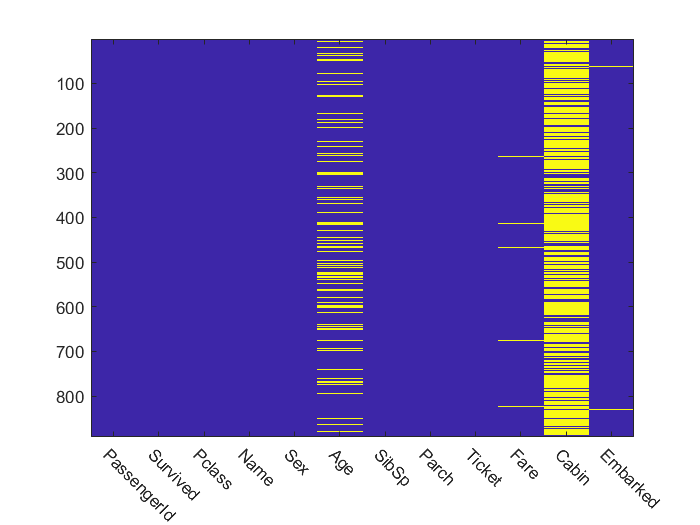

Train.Fare(Train.Fare == 0) = NaN;      % treat 0 fare as NaN
Train.Fare(Train.Fare == 0) = NaN;        % treat 0 fare as NaN
vars = Train.Properties.VariableNames;  % extract column names
figure
imagesc(ismissing(Train))
set(gca,'XTick', 1:12,'XTickLabel',vars);
xtickangle(-45)

% Using the average age replace NaN age
avgAge = nanmean(Train.Age)             % get average age

avgAge = 29.6991

Train.Age(isnan(Train.Age)) = avgAge;   % replace NaN with the average
Test.Age(isnan(Test.Age)) = avgAge; 


% Replace the NaN Fare with the average fare of the correspoinding Pclass
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % get class average
disp(fare)

         Pclass    GroupCount    mean_Fare
         ______    __________    _________

    1    1         216           86.149   
    2    2         184           21.359   
    3    3         491           13.788   



for i = 1:height(fare) % for each |Pclass|
    % apply the Pclass average to missing values
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end

% Multi Cabins，No Cabin etc.

train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false);
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false);
 
% count the number of tokens
Train.nCabins = cellfun(@length, train_cabins);
Test.nCabins = cellfun(@length, test_cabins);
 
% deal with exceptions - only the first class people had multiple cabins
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;
 
% if |Cabin| is empty, then |nCabins| should be 0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0;
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

% Embarked is not available
% get most frequent value
disp(grpstats(Train(:,{'Survived','Embarked'}), 'Embarked'))

         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    S    'S'         644           0.33696      
    C    'C'         168           0.55357      
    Q    'Q'          77           0.38961      



 
% apply it to missling value
for i = 1 : 891
    if isempty(Train.Embarked{i})
        Train.Embarked{i}='S';
    end
end
 
for i = 1 : 418
    if isempty(Test.Embarked{i})
        Test.Embarked{i}='S';
    end
end
 
% convert the data type from categorical to double
Train.Embarked = double(cell2mat(Train.Embarked))

Train = 891×13 table
    PassengerId    Survived    Pclass                            Name                               Sex        Age      SibSp    Parch          Ticket           Fare     Cabin     Embarked    nCabins
    ___________    ________    ______    _____________________________________________________    ________    ______    _____    _____    __________________    ______    ______    ________    _______

     1             0           3         'Braund, Mr. Owen Harris'                                'male'          22    1        0      

Test.Embarked = double(cell2mat(Test.Embarked));

% change Sex to tpye "double"
for i = 1 : 891
    if strcmp(Train.Sex{i} ,'male')
        Train.Sex{i}=1;
    else
        Train.Sex{i}=0;
    end
end
 
for i = 1 : 418
    if strcmp(Test.Sex{i} ,'male')
        Test.Sex{i}=1;
    else
        Test.Sex{i}=0;
    end
end
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);

% Del some columns
Train(:,{'Name','Ticket','Cabin'}) = [];
Test(:,{'Name','Ticket','Cabin'}) = [];


## Visulization

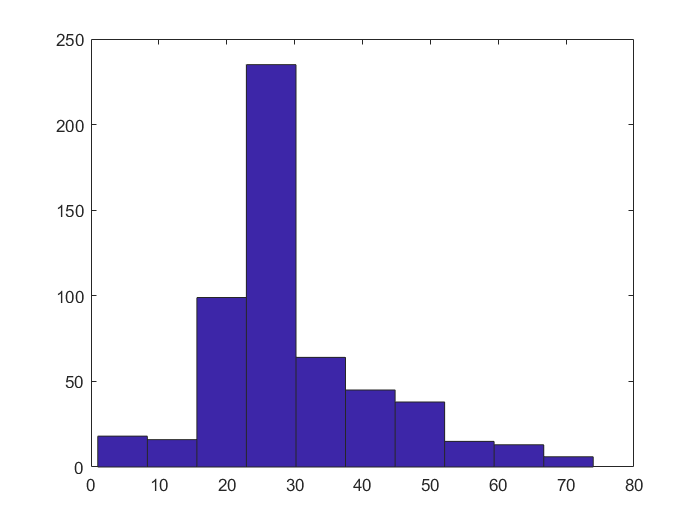


% Age - survived
figure
hist (Train.Age(Train.Survived == 0))   % age histogram of non-survivers

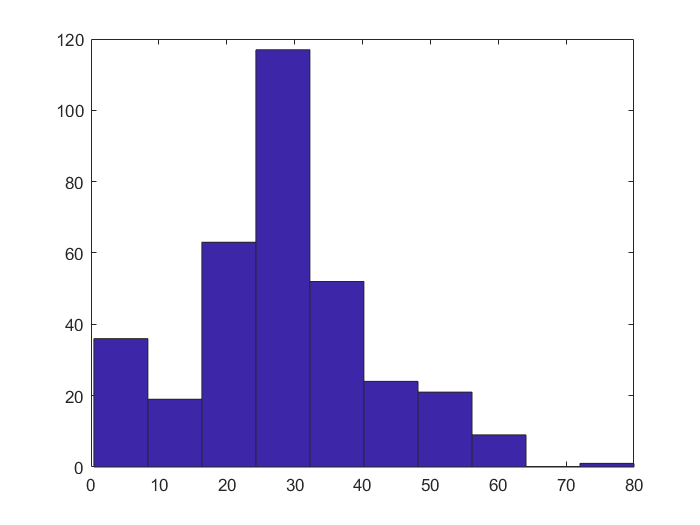

figure
hist (Train.Age(Train.Survived == 1))   % age histogram of survi

data = Train.Variables;
t = data(:,3:10);
l = data(:,2);
X = t';
X = zscore(X,0,2);
X = [X;ones(1,891)];
y = (l*2-1)';
idx = randperm(891);
X_train = X(:,idx(1:700));
y_train = y(idx(1:700));
X_test = X(:,idx(701:891));
y_test = y(idx(701:891));
y_aug = repmat(y_train,9,1);








%计算类标记
ps1=sum(Train.Survived == 1)/(sum(Train.Survived == 1 )+sum(Train.Survived == 0))

ps1 = 0.3838

pd0=sum(Train.Survived == 0)/(sum(Train.Survived == 1)+sum(Train.Survived == 0))

pd0 = 0.6162

%展示

%使用标签Train.Pclass  Train.Sex
%计算条件概率

       
         a= Train.Sex(Train.Survived==1);
         b=Train.Sex(Train.Survived==0);
         c= Train.Pclass(Train.Survived==1);
         d= Train.Pclass(Train.Survived==0);
         p0=sum(a == 0)/sum(Train.Survived == 1);
         p1=sum(a == 1)/sum(Train.Survived == 1);
         p2=sum(b == 0)/sum(Train.Survived == 0);
         p3=sum(b == 1)/sum(Train.Survived == 0);
         p4=sum(c == 1)/sum(Train.Survived == 1);
         p5=sum(c == 2)/sum(Train.Survived == 1);
         p6=sum(c == 3)/sum(Train.Survived == 1);
         p7=sum(d == 1)/sum(Train.Survived == 0);
         p8=sum(d == 2)/sum(Train.Survived == 0);
         p9=sum(d == 3)/sum(Train.Survived == 0);
          
        
%计算最终概率
      
for i=1:418
    data= Test.Variables;
  
 
   if  data(i,3)==0 && data(i,2)==1
       pa = ps1*p0*p4;
     pb=pd0*p2*p7;
   end
 if(data(i,3)==0 && data(i,2)==2)
      pa=ps1*p0*p5;
     pb=pd0*p2*p8;
 end
 if(data(i,3)==0 && data(i,2)==3)
       pa=ps1*p0*p6;
     pb=pd0*p2*p9;
 end
 if(data(i,3)==1 && data(i,2)==1)
      pa=ps1*p1*p4;
     pb=pd0*p3*p7;
 end
 if(data(i,3)==1 && data(i,2)==2)
       pa=ps1*p1*p5;
     pb=pd0*p3*p8;
 end
 if(data(i,3)==1 && data(i,2)==3) 

      pa=ps1*p1*p6;
     pb=pd0*p3*p9;
 end
  if(pa>pb)
      survived(i,1)=1;
  else
     survived(i,1)=0;
   end
end
PassengerId=Test.PassengerId;
Survived=survived;
   result_table= table(PassengerId,Survived);
   writetable(result_table, 'F:/submission.csv')
 